# Experiment No 01

Transfer Function of an Electrical Circuit 

Prepared by Ganesh N. Jadhav, KKWIEER, Nashik, India 422003

## Prelab session

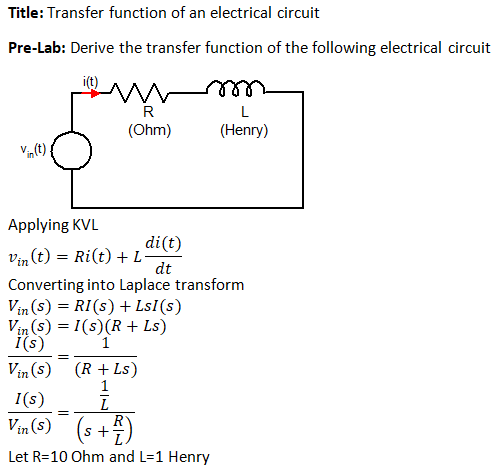

## Lab session

% Input parameters
R=10; % in Ohm
L=1;  % in Henry
% Transfer function
num=[1/L]

num = 1

den=[1 R/L]

den =      1    10


sys=tf(num,den)

sys =
 
    1
  ------
  s + 10
 
Continuous-time transfer function.
Model Properties


% Pole, zeros and constants of the tranfer function
sys_zpk=zpk(sys);
disp('Zeros')

Zeros


disp(sys_zpk.Z)

    {0×1 double}



disp('Poles')

Poles


disp(sys_zpk.P)

    {[-10]}



disp('Gain')

Gain


disp(sys_zpk.K)

     1



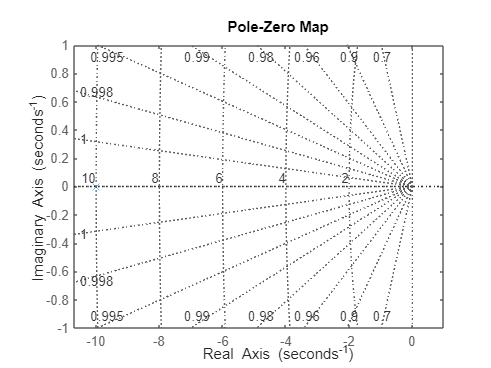

pzplot(sys)
xlim("padded");    ylim("padded");
grid on

## Post lab

% Effect of parameter varaition
% From the slider change in values of R and L 
% Observe the impact on zeros, poles and gain of the system
% Input parameters
R=5; % in Ohm
L=0.9;  % in Henry
% Transfer function
num=[1/L]

num = 1.1111

den=[1 R/L]

den =     1.0000    5.5556


sys=tf(num,den)

sys =
 
    1.111
  ---------
  s + 5.556
 
Continuous-time transfer function.
Model Properties


% Pole, zeros and constants of the tranfer function
sys_zpk=zpk(sys);
disp('Zeros')

Zeros


disp(sys_zpk.Z)

    {0×1 double}



disp('Poles')

Poles


disp(sys_zpk.P)

    {[-5.5556]}



disp('Gain')

Gain


disp(sys_zpk.K)

    1.1111



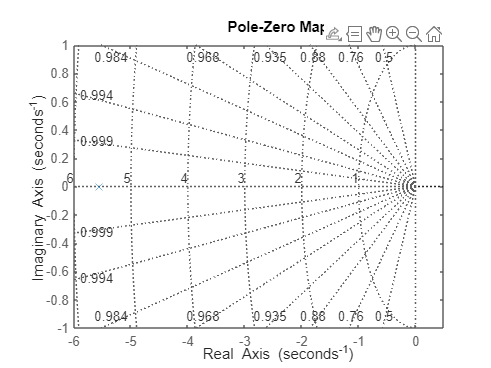

pzplot(sys)
xlim("padded");    ylim("padded");
grid on